# Symmetric Concave Quadratic Chirp  %凹形二次调频信号

Generate a concave quadratic chirp sampled at 1 kHz for 4 seconds. Specify the time vector so that the instantaneous frequency is symmetric about the halfway point of the sampling interval, with a minimum frequency of 100 Hz and a maximum frequency of 500 Hz.

%生成一个采样率为 1khz、持续时间为 4 秒的凹形二次调频信号。指定时间向量，使得瞬时频率关于采样间隔的中点对称，最低频率为 100 赫兹，最高频率为 500 赫兹。

编辑分享

t = -2:1/1e3:2;
fo = 100;
f1 = 200;
y = chirp(t,fo,1,f1,'quadratic',[],'concave');
%用来生成一个非线性扫频信号（chirp 信号）的
%使用了 MATLAB 中的 chirp 函数，其中扫频方式为二次曲线（quadratic），频率变化是向内凹（concave)的

Compute and plot the spectrogram of the chirp. Divide the signal into segments such that the time resolution is 0.1 second. Specify 99% of overlap between adjoining segments and a spectral leakage of 0.85.

%计算并绘制该线性调频信号的频谱图。将信号分割成若干段，使时间分辨率为0.1秒。指定相邻段之间的重叠率为99%，频谱泄漏为0.85。

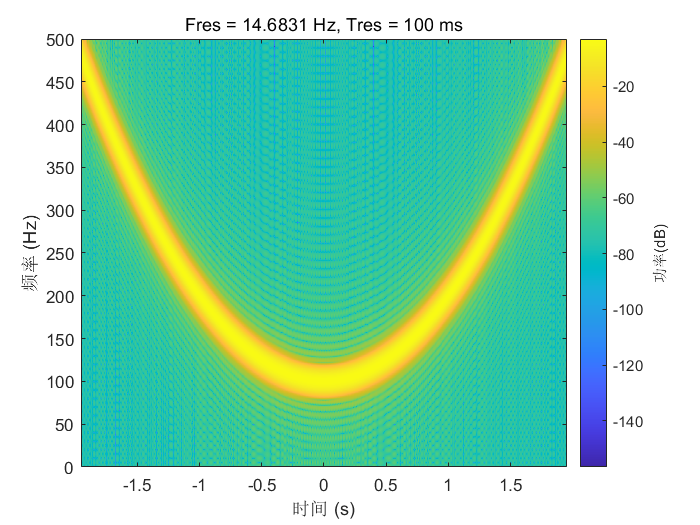

pspectrum(y,t,'spectrogram','TimeResolution',0.1, ...
    'OverlapPercent',99,'Leakage',0.85)

*Copyright 2015 The MathWorks, Inc.*

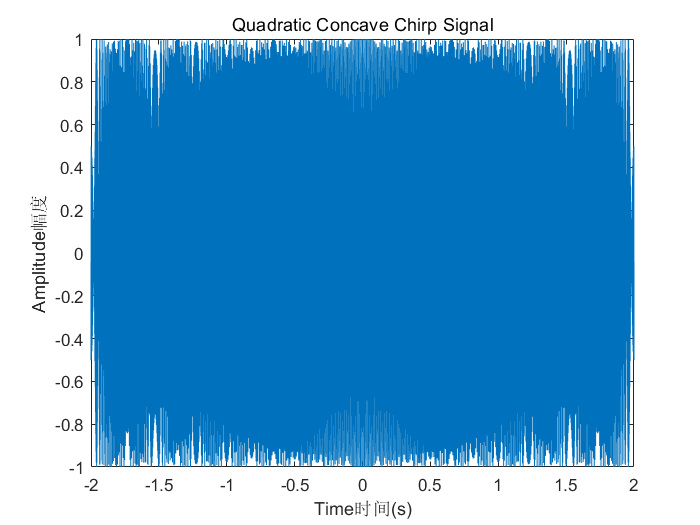

plot(t, y); title('Quadratic Concave Chirp Signal'); xlabel('Time时间(s)'); ylabel('Amplitude幅度');

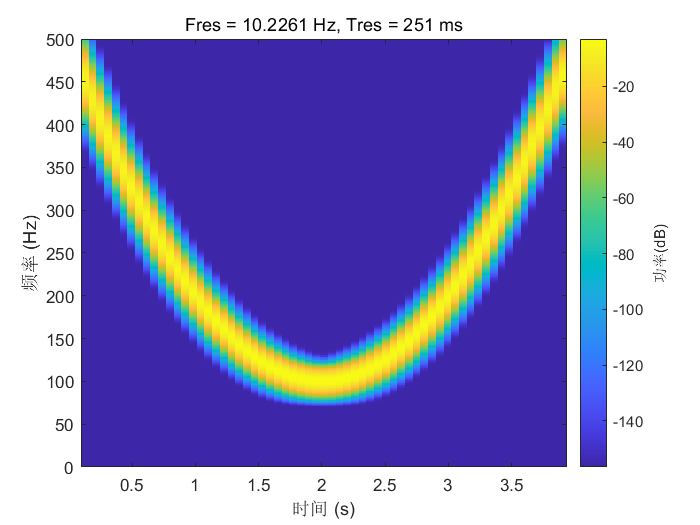


% 或者画频率随时间的变化（频率包络）
% 
% 
% | 参数              | 含义                                                  |
% | --------------- | --------------------------------------------------- |
% | `y`             | 要分析的信号（这里是扫频信号 `chirp` 输出）                          |
% | `1000`          | 采样率 `Fs = 1000 Hz`，你在前面定义 `t = -2:1/1000:2`，就是这个采样率 |
% | `'spectrogram'` | 指定分析方式为**频谱图（Spectrogram）**，即时频图                    |

pspectrum(y, 1000, 'spectrogram')
